clear all
close all
data = get_hippo_data();
data = rmmissing(data);
data = data{:, :}

data = 1.0e+03 *

         0    0.1675    0.0026    0.0071    0.2390    0.0040    0.0100    0.8005    0.0040         0    0.1523
    0.0000    0.1675    0.0026    0.0071    0.2390    0.0040    0.0100    0.8004    0.0040         0    0.1523
    0.0000    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.8009    0.0038         0    0.1523
    0.0000    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.7995    0.0038         0    0.1523
    0.0000    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.7999    0.0038         0    0.1523
    0.0001    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.8017    0.0038         0    0.1523
    0.0001    0.1675    0.0026    0.0072    0.2398    0.0040    0.0100    0.8005    0.0038         0    0.1520
    0.0001    0.1670    0.0026    0.0072    0.2398    0.0040    0.0100    0.7998    0.0038         0    0.1520
    0.0001    0.1670    0.0026    0.0072    0.2398    0.0040    0.0100    0.7999    0.0038    

data

data = 1.0e+03 *

         0    0.1675    0.0026    0.0071    0.2390    0.0040    0.0100    0.8005    0.0040         0    0.1523
    0.0000    0.1675    0.0026    0.0071    0.2390    0.0040    0.0100    0.8004    0.0040         0    0.1523
    0.0000    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.8009    0.0038         0    0.1523
    0.0000    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.7995    0.0038         0    0.1523
    0.0000    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.7999    0.0038         0    0.1523
    0.0001    0.1675    0.0026    0.0072    0.2390    0.0040    0.0100    0.8017    0.0038         0    0.1523
    0.0001    0.1675    0.0026    0.0072    0.2398    0.0040    0.0100    0.8005    0.0038         0    0.1520
    0.0001    0.1670    0.0026    0.0072    0.2398    0.0040    0.0100    0.7998    0.0038         0    0.1520
    0.0001    0.1670    0.0026    0.0072    0.2398    0.0040    0.0100    0.7999    0.0038    

train_size = 100000;
test_size = 10000;
numTrainTimesteps = 10;
dataTrain = data(1:train_size, :);
dataTest = data(train_size + 1:train_size+test_size, :);
XTrain = cell(train_size-numTrainTimesteps-1, 1);
TTrain = cell(train_size-numTrainTimesteps-1, 1);
XTest = cell(test_size-numTrainTimesteps-1, 1);
TTest = cell(test_size-numTrainTimesteps-1, 1);
for n=1:train_size - numTrainTimesteps-1
    last_timestamp = n+numTrainTimesteps;
    XTrain{n} = reshape(dataTrain(n:n+numTrainTimesteps, 3:6), [4, 11]);
    TTrain{n} = dataTrain(last_timestamp+1, 2);
end
for n=1:test_size - numTrainTimesteps-1
    last_timestamp = n+numTrainTimesteps;
    XTest{n} = reshape(dataTest(n:last_timestamp, 3:6), [4, 11]);
    TTest{n} = dataTest(last_timestamp+1, 2);
end

x_3d = reshape(cell2mat(XTrain),[4, 11, 99989])

x_3d = x_3d(:,:,1) =

    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000
    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000
    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000
    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000


x_3d(:,:,2) =

    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000
    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000
    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000
    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000    2.6000


x_3d(:,:,3) =

    2.6000    2.6000    2.6000    2.6000    2.6000    2.

dlX = dlarray(x_3d,'CTB');

%XTrain= cell2mat(permute(XTrain,[1,3,2]))(XTrain);
TTrain= cell2mat(TTrain);
TTest= cell2mat(TTest);

muX = mean(cell2mat(XTrain),1);
sigmaX = std(cell2mat(XTrain),1);

muT = mean(cell2mat(TTrain));
sigmaT = std(cell2mat(TTrain),1);

for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n} - muX) ./ sigmaX;
    TTrain{n} = (TTrain{n} - muT) ./ sigmaT;
end

inputSize = 4;
numHiddenUnits = 100;
numClasses = 1;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,OutputMode="last")
    %lstmLayer(numHiddenUnits,OutputMode="last")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

maxEpochs = 10;
miniBatchSize = 1000;

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=maxEpochs, ...
    ExecutionEnvironment="gpu", ...
    Plots="training-progress", ...
    Verbose=false);

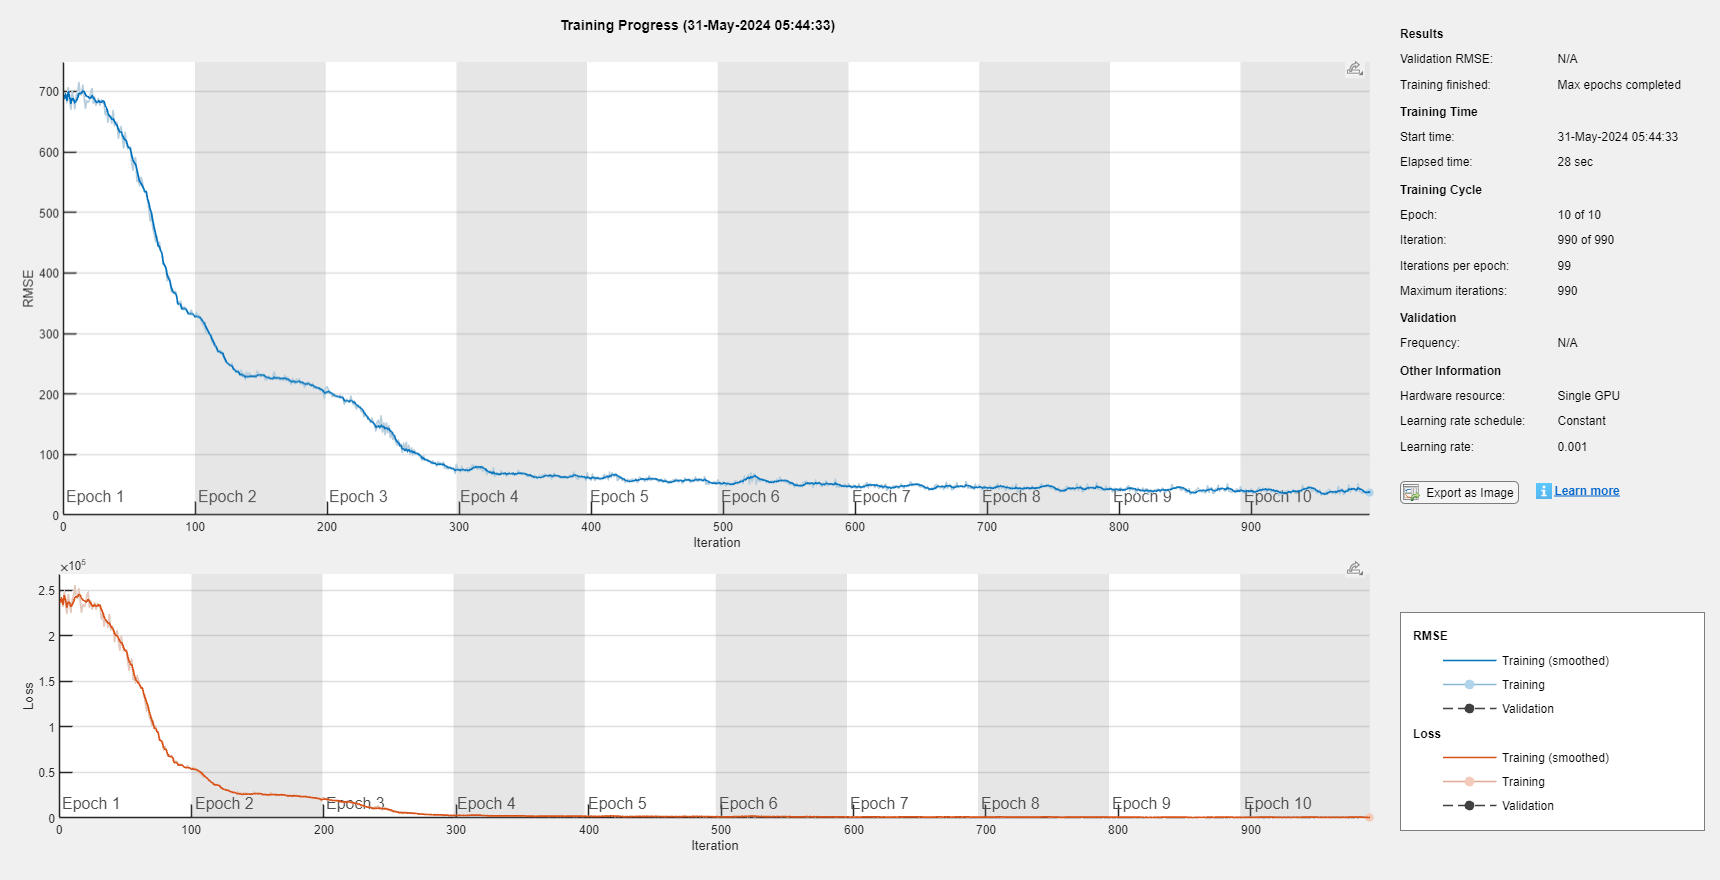

net = trainNetwork(XTrain,TTrain,layers,options);

net = trainNetwork(XTrain,TTrain,net.Layers,options);

net =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}
